# Gauss-Seidel for Tensor-Regression Video Deblur

clear;clc;close all;
addpath('../deblurring')
addpath('../tproduct toolbox 2.0 (transform)/')

openfig('figs/tRGS_deblurring_error_zeroinitialization.fig')

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


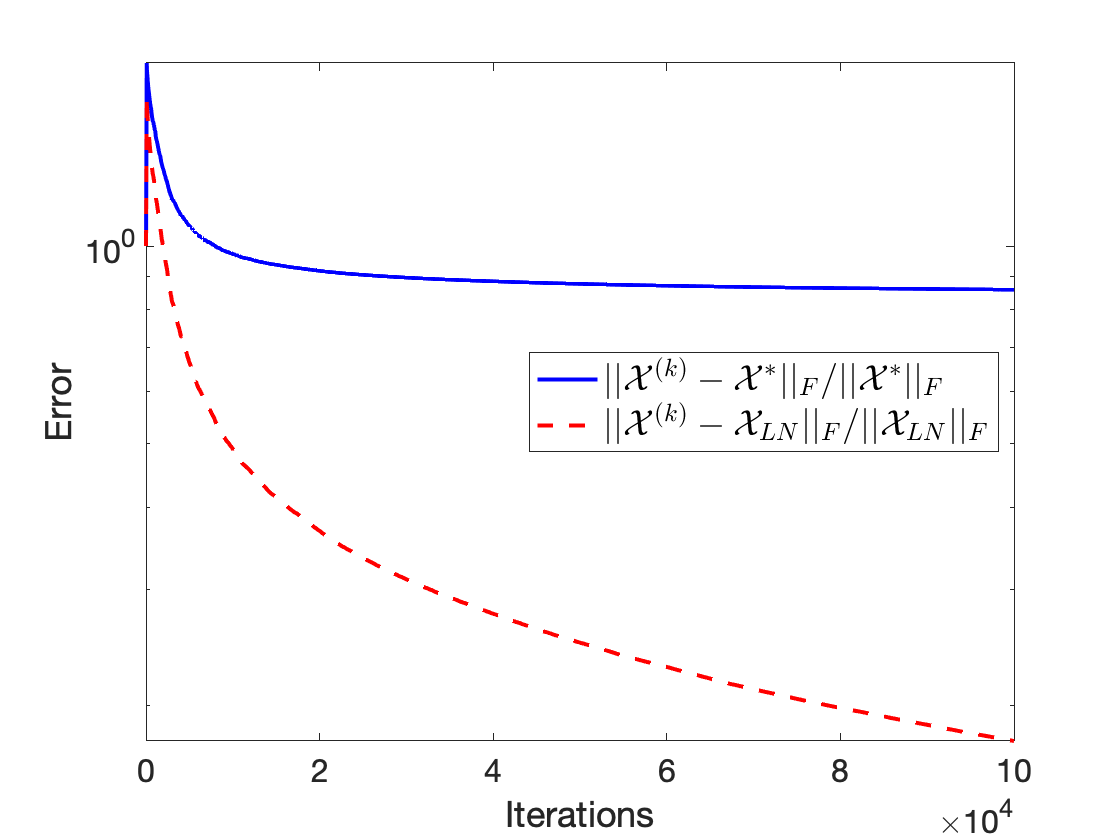

set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F/||\mathcal{X}^*||_F$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F/||\mathcal{X}_{LN}||_F$','FontSize',18,'Interpreter','latex','Location','east')
savefig('figs/tRGS_deblurring_error_zeroinitialization.fig')
saveas(gcf,'figs/tRGS_deblurring_error_zeroinitialization.png')


% openfig('figs/tRGS_deblurring_energy_zeroinitialization.fig')
% set(gca,'FontSize',16)
% xlabel('Iterations','FontSize',18) 
% ylabel('Energy','FontSize',18)
% legend('$||\mathcal{X}^{(k)}||_F$', '$||\mathcal{X}^*||_F^2$', '$||\mathcal{X}_{LN}||_F^2$','FontSize',18,'Interpreter','latex','Location','southwest')
% savefig('figs/tRGS_deblurring_energy_zeroinitialization.fig')
% saveas(gcf,'figs/tRGS_deblurring_energy_zeroinitialization.png')


### Initializing with Noisy Image

openfig('figs/tRGS_deblurring_error_blurryinitialization.fig')

ans =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


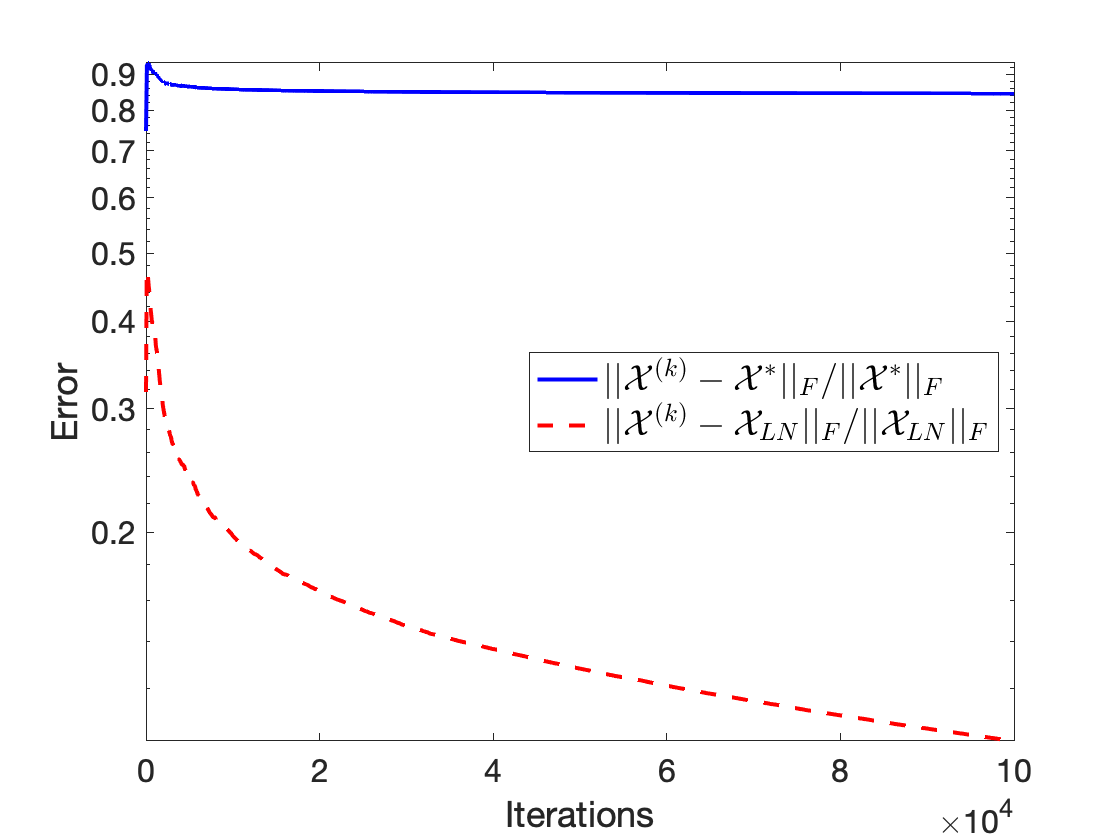

set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F/||\mathcal{X}^*||_F$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F/||\mathcal{X}_{LN}||_F$','FontSize',18,'Interpreter','latex','Location','east')
savefig('figs/tRGS_deblurring_error_blurryinitialization.fig')
saveas(gcf,'figs/tRGS_deblurring_error_blurryinitialization.png')

% 
% figure(5);
% plot(0:num_its,norms,'b-',0:num_its,norm(X(:))*ones([1,num_its+1]),'r--',0:num_its,norm(X_ln(:))*ones([1,num_its+1]),'k-.','LineWidth',2)
% set(gca,'FontSize',16)
% xlabel('Iterations','FontSize',18) 
% ylabel('Energy','FontSize',18)
% legend('$||\mathcal{X}^{(k)}||_F$', '$||\mathcal{X}^*||_F^2$', '$||\mathcal{X}_{LN}||_F^2$','FontSize',18,'Interpreter','latex','Location','southwest')
% savefig('figs/tRGS_deblurring_energy_blurryinitialization.fig')
% saveas(gcf,'figs/tRGS_deblurring_energy_blurryinitialization.png')


### Initializing randomly

openfig('figs/tRGS_deblurring_error_randinitialization.fig')

ans =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


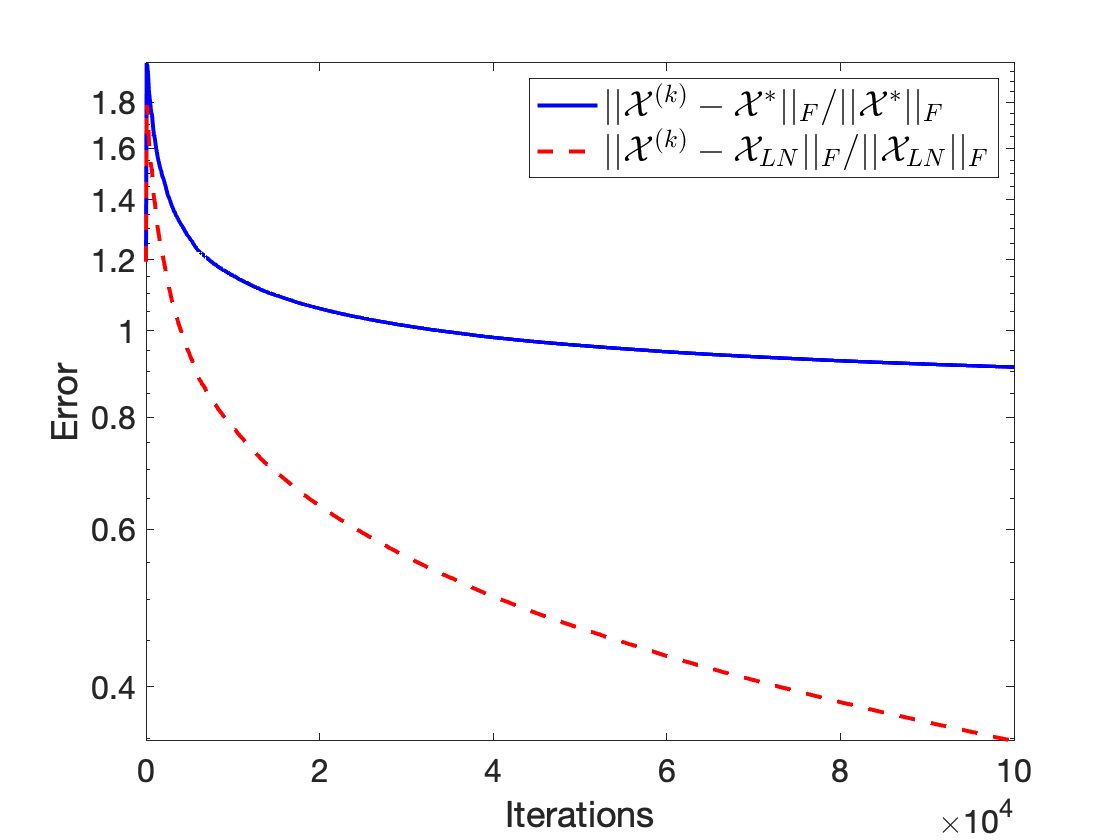

set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F/||\mathcal{X}^*||_F$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F/||\mathcal{X}_{LN}||_F$','FontSize',18,'Interpreter','latex','Location','northeast')
savefig('figs/tRGS_deblurring_error_randinitialization.fig')
saveas(gcf,'figs/tRGS_deblurring_error_randinitialization.png')

% 
% figure(8);
% plot(0:num_its,norms,'b-',0:num_its,norm(X(:))*ones([1,num_its+1]),'r--',0:num_its,norm(X_ln(:))*ones([1,num_its+1]),'k-.','LineWidth',2)
% set(gca,'FontSize',16)
% xlabel('Iterations','FontSize',18) 
% ylabel('Energy','FontSize',18)
% legend('$||\mathcal{X}^{(k)}||_F$', '$||\mathcal{X}^*||_F^2$', '$||\mathcal{X}_{LN}||_F^2$','FontSize',18,'Interpreter','latex','Location','southwest')
% savefig('figs/tRGS_deblurring_energy_randinitialization.fig')
% saveas(gcf,'figs/tRGS_deblurring_energy_randinitialization.png')


openfig('figs/tRGS_deblurring_reserror.fig')

ans =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('$||\mathcal{A} \mathcal{X}^{(k)} - \mathcal{B}||_F$','FontSize',18,'Interpreter','latex') 
legend('zero initialization', 'blurry initialization', 'random initialization','FontSize',18,'Interpreter','latex','Location','northeast')
savefig('figs/tRGS_deblurring_reserror.fig')
saveas(gcf,'figs/tRGS_deblurring_reserror.png')